## Report Part

a) In the first question, I was asked to train 25 different pairs of models with 8 guassian mixtures and plot their corresponding error rates with dimensions. 

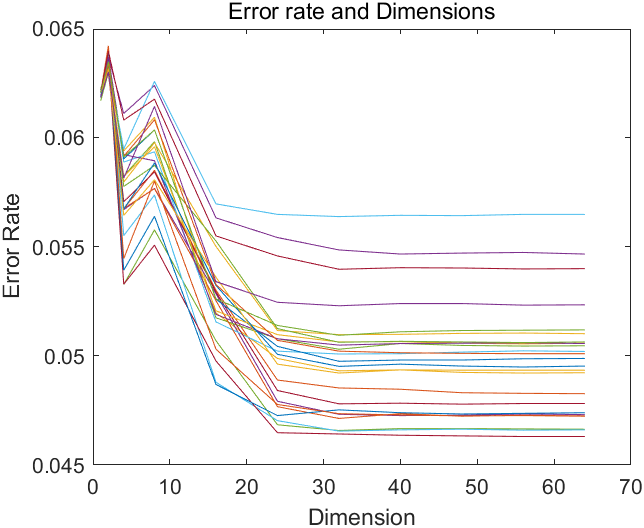

From this graph, where each line represents a mixture pair. We can see overall the error rate goes down when dimension goes up. However we do notices there is a local minimum when dimension is equal to 4. This may because the 4th feature in the dataset is far more distinct between two class than other features within first 10 features. Overall, when the number of dimensions goes up, the difference between each pair also goes up, which means random initialization has its inevitable draw backs. 

b) In this question, we have many options of number of mixtures. Their corresponding error rates with dimensions is shown here:

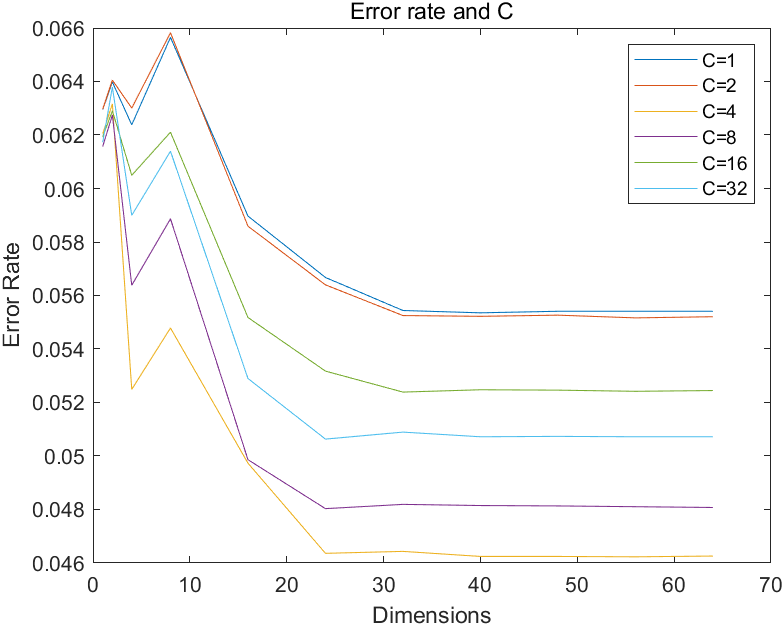

As we can see the error rate also goes down when dimension goes up. Furthermore, we can see the average error rate is low when c is equal to 4 or 8. When the mixtures is too low, the error rate is relativly high.

## Code Part

load('TrainingSamplesDCT_8_new.mat');
C=8;
mixtures=5;
priorBG=size(TrainsampleDCT_BG,1)/(size(TrainsampleDCT_FG,1)+size(TrainsampleDCT_BG,1));
priorFG=size(TrainsampleDCT_FG,1)/(size(TrainsampleDCT_FG,1)+size(TrainsampleDCT_BG,1));
dim=[1,2,4,8,16,24,32,40,48,56,64];


a) first train all the parameters for each mixture pair for each class and store them into an array

% Train the mixture models for background
all_prior_bg=ones(C,mixtures);
all_mean_bg=ones(C,64,mixtures);
all_var_bg=ones(C,64,mixtures);
for n=1:5
    [prior_bg,mean_bg,var_bg]=EM(64,C,TrainsampleDCT_BG);
    all_prior_bg(:,n)=prior_bg;
    all_mean_bg(:,:,n)=mean_bg;
    for i=1:C
        all_var_bg(i,:,n)=diag(var_bg(:,:,i));
    end
end


% Train the mixture models for foreground
all_prior_fg=ones(C,mixtures);
all_mean_fg=ones(C,64,mixtures);
all_var_fg=ones(C,64,mixtures);
for n=1:5
    [prior_fg,mean_fg,var_fg]=EM(64,C,TrainsampleDCT_FG);
    all_prior_fg(:,n)=prior_fg;
    all_mean_fg(:,:,n)=mean_fg;
    for i=1:C
        all_var_fg(i,:,n)=diag(var_fg(:,:,i));
    end
end


% classify image using 25 pairs of mixtures
I=imread('cheetah.bmp');
I=im2double(I);

check=imread('cheetah_mask.bmp');
check=im2double(check);

all_error=zeros(25,11);
error_pointer=1;
for i=1:5
    for j=1:5
        errorate=zeros(11,1);
        pointer=1;
        mean_bg_ij=all_mean_bg(:,:,i);
        mean_fg_ij=all_mean_fg(:,:,j);
        
        prior_bg_ij=all_prior_bg(:,i);
        prior_fg_ij=all_prior_fg(:,j);
        
        var_bg_ij=zeros(64,64,C);
        var_fg_ij=zeros(64,64,C);
        for k=1:C
            var_bg_ij(:,:,k)=diag(all_var_bg(k,:,i));
            var_fg_ij(:,:,k)=diag(all_var_fg(k,:,j));
        end
        for d=[1,2,4,8,16,24,32,40,48,56,64]
            A_pre= zeros(255,270);
            for m=1:248
                for n=1:263
                    each = I(m:m+7,n:n+7);
                    each = dct2(each);
                    each = zigzag_scan(each);
                    each = each(:,[1:d]);
                    
                    sliced_var_bg=zeros(d,d,C);
                    sliced_var_fg=zeros(d,d,C);
                    for k=1:C
                        whole_bg=diag(var_bg_ij(:,:,k));
                        sliced_var_bg(:,:,k)=diag(whole_bg([1:d],:));
                        
                        whole_fg=diag(var_fg_ij(:,:,k));
                        sliced_var_fg(:,:,k)=diag(whole_fg([1:d],:));
                    end
                    
                    if calculate_prob(each,mean_fg_ij(:,[1:d]),sliced_var_fg,prior_fg_ij,C)*priorFG>calculate_prob(each,mean_bg_ij(:,[1:d]),sliced_var_bg,prior_bg_ij,C)*priorBG
                        A_pre(m,n)=1;
                    end
                end
            end
            errorate(pointer)=sum(sum(xor(check, A_pre))) / (255*270);
            pointer=pointer+1;
            disp(['dim ',num2str(d),' done']);
        end
        all_error(error_pointer,:)=errorate';
        error_pointer=error_pointer+1;
        disp('next combination');
        plot(dim,errorate);
        title('Error rate and Dimensions');
        hold on
    end
end


b) For each C, train parameters for each class, and plot the graph.

C=[1,2,4,8,16,32];
I=imread('cheetah.bmp');
I=im2double(I);

check=imread('cheetah_mask.bmp');
check=im2double(check);

all_error_c=zeros(6,11);
error_pointer=1;
hold off;
figure;
for i=C
    [prior_bg_c,mean_bg_c,var_bg_c]=EM(64,i,TrainsampleDCT_BG);
    [prior_fg_c,mean_fg_c,var_fg_c]=EM(64,i,TrainsampleDCT_FG);
    errorate_c=zeros(11,1);
    pointer=1;
    for d=[1,2,4,8,16,24,32,40,48,56,64]
            A_pre= zeros(255,270);
            for m=1:248
                for n=1:263
                    each = I(m:m+7,n:n+7);
                    each = dct2(each);
                    each = zigzag_scan(each);
                    each = each(:,[1:d]);
                    
                    sliced_var_bg=zeros(d,d,i);
                    sliced_var_fg=zeros(d,d,i);
                    for k=1:i
                        whole_bg=diag(var_bg_c(:,:,k));
                        sliced_var_bg(:,:,k)=diag(whole_bg([1:d],:));
                        
                        whole_fg=diag(var_fg_c(:,:,k));
                        sliced_var_fg(:,:,k)=diag(whole_fg([1:d],:));
                    end
                    
                    if calculate_prob(each,mean_fg_c(:,[1:d]),sliced_var_fg,prior_fg_c,i)*priorFG>calculate_prob(each,mean_bg_c(:,[1:d]),sliced_var_bg,prior_bg_c,i)*priorBG
                        A_pre(m,n)=1;
                    end
                end
            end
         errorate_c(pointer)=sum(sum(xor(check, A_pre))) / (255*270);
         pointer=pointer+1;
    end
    all_error_c(error_pointer,:)=errorate_c';
    error_pointer=error_pointer+1;
    disp('next c');
    plot(dim,errorate_c);
    title('Error rate and C');
    xlabel('Dimensions')
    ylabel('Error Rate')
    hold on
end

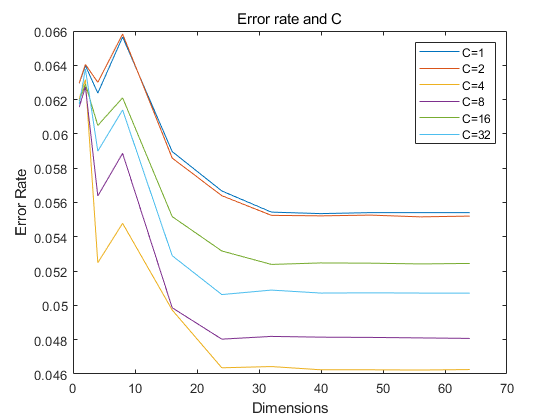

figure;
for i=1:6
    plot(dim,all_error_c(i,:),'DisplayName',['C=',num2str(C(i))]);
    title('Error rate and C');
    xlabel('Dimensions')
    ylabel('Error Rate')
    legend();
    hold on
end

function [prior_final,mean_final,var_final]=EM(di,c,x)
%     initialize the parameters
    prior_rand=ones(c,1)./c;
    mean_rand=rand(c,di);
    var_rand=zeros(di,di,c);
    for i=1:c
        var_rand(:,:,i)=diag(0.001+rand(di,1));
    end
%     initialize h matrix
    global h;
    h=ones(size(x,1),c);
    
    for n=1:100
%         E step
        for i=1:size(x,1)
            for j=1:c
%            calculate h(ij)
                h(i,j)=mvnpdf(x(i,:),mean_rand(j,:),var_rand(:,:,j))*prior_rand(j);
            end
            h(i,:)=h(i,:)/sum(h(i,:));
        end
%         M step
        prior_final=prior_rand;
        mean_final=mean_rand;
        var_final=var_rand;
        for j=1:c
%             update mean_final and prior_final
            mean_rand(j,:)=h(:,j)'*x./sum(h(:,j));
            prior_rand(j)=sum(h(:,j))/size(x,1);
            var_num=0;
%             update variance
            for i=1:size(x,1)
                var_num=var_num+h(i,j)*(x(i,:)-mean_rand(j,:)).^2;
            end
            temp_var=var_num/sum(h(:,j));
            temp_var(temp_var<0.002)=0.002;
            var_rand(:,:,j)=diag(temp_var);
        end
        if max(max(abs(mean_final-mean_rand)./abs(mean_final)))<0.01
            break
        end
        prior_final=prior_rand;
        mean_final=mean_rand;
        var_final=var_rand;
    end
end

function A=zigzag_scan(m)
    ZigZagPattern=[
        0   1   5   6  14  15  27  28;
        2   4   7  13  16  26  29  42;
        3   8  12  17  25  30  41  43;
        9  11  18  24  31  40  44  53;
        10  19  23  32  39  45  52  54;
        20  22  33  38  46  51  55  60;
        21  34  37  47  50  56  59  61;
        35  36  48  49  57  58  62  63
        ];
    ZigZagPattern=ZigZagPattern+1;
    A=zeros(1,64);
    for i=1:8
        for j=1:8
            A(ZigZagPattern(i,j))=m(i,j);
        end
    end
end

function prob=calculate_prob(x,mu,sig,prior,c)
    prob=0;
    for j=1:c
        prob=prob+mvnpdf(x,mu(j,:),sig(:,:,j))*prior(j);
    end
end